# `wfft`

窓関数付きフーリエ変換

## 構文

## 説明

`Fy = wfft(y, x) はy全体をフーリエ変換した結果を返します．`

`Fy = wfft(y, x, xStart, xEnd) `は`x`の軸の`xStart`から`xEnd`の範囲に対して対応する`y`をフーリエ変換します．フーリエ変換の結果は`Fy`として返されます．

`Fy = wfft(y, x, xStart, xEnd, expandPts) `は`expandPts`が`y`の大きさよりも大きい場合，`expandPts`まで`0`を追加してフーリエ変換を行います．

`Fy = wfft( ___, Name=Value) `は，名前と値の引数を使用して追加オプションを指定します．オプションにはウィンドウの形状，零点補正の有無，方法などが含まれます．

`[Fy, Fx] = wfft( ___ ) `はフーリエ変換の結果`Fy`に対する周波数軸`Fx`を返します．

`[Fy, Fx, beforeFFT] = wfft( ___ ) `はフーリエ変換直前の波形（零点補正・窓関数・ゼロパディング後）`beforeFFT`を返します．正しい位置に窓がかけられているかなどをチェックするのに有効です．

`[Fy, Fx, beforeFFT, windowFun] = wfft( ___ ) `は窓関数の関数ハンドルを返します．`y`に掛けられるベクトルは`windowFun(timevec)`で求めることができます．

出力引数を設定せずに`wfft( ___ )`を使用すると，現在の`Figure`ウィンドウに， 変換前の時間波形とフーリエ変換結果を並べて表示します．この方法は，結果を最初に確認するのに向いています． 

## 例

wfft_example.mも参照ください．

### 窓関数で解析範囲を限定したフーリエ変換

`窓を用いたフーリエ変換の例を示します．まずフーリエ変換のためのデータを用意します．ここではx,yという変数にそれぞれ時間軸ベクトルと，波形ベクトルを読み込みます．どのような波形かをプロットして確認しておきます．`

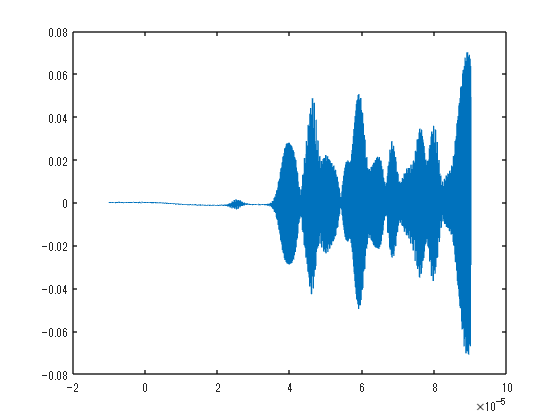

load('test_data\data20231127-113905-trimed.mat'); %テスト用波形読み込み(timevec, waveform1, waveform2, waveform1and2を含む)
y = waveform1and2; %フーリエ変換対象の波形
x = timevec;       %フーリエ変換対象の波形の時間軸
plot(x,y)

`40μsから52μsの範囲に窓をかけてフーリエ変換します．フーリエ変換の結果はFyに格納されます．また，周波数ベクトルもFxとして保存されます．`

xStart = 40e-6; %窓関数をかける時間範囲（左端）
xEnd = 52e-6;   %窓関数をかける時間範囲（右端）
[Fy, Fx] = common.wfft(y,x,xStart,xEnd);

フーリエ変換の結果を表示します．

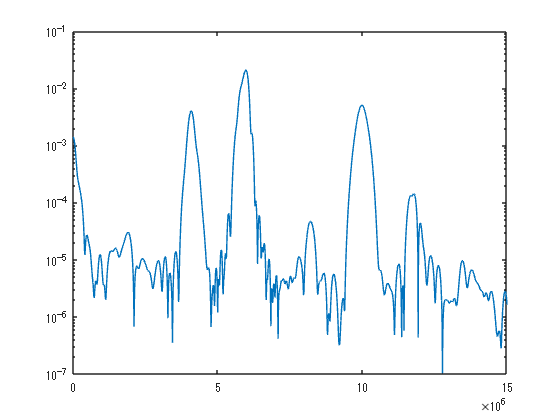

semilogy(Fx, Fy);
xlim([0 15e6]);

この信号の`40μsから52μsの範囲`には，約4 MHz，6 MHz，10 MHzの成分が含まれていることを示しています．

### フーリエ変換をかけた範囲を確認する

返り値を指定しない場合，元の波形とフーリエ変換後のFFT結果のプレビューを見れます．大きなミスをしていないかなどの確認に有効です．

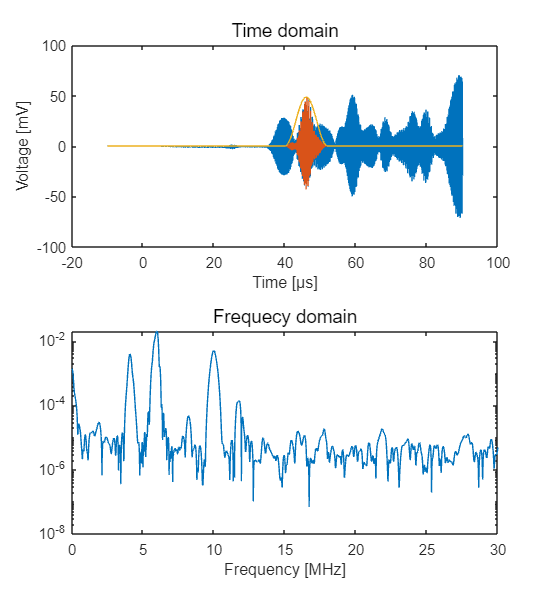

load('test_data\data20231127-113905-trimed.mat'); %テスト用波形読み込み(timevec, waveform1, waveform2, waveform1and2を含む)
y = waveform1and2; %フーリエ変換対象の波形
x = timevec;       %フーリエ変換対象の波形の時間軸
figure()
common.wfft(y,x,xStart,xEnd);

### フーリエ変換の窓関数を指定する

窓関数の形状はフーリエ変換のローブの形に影響を与えます．

デフォルトではハン窓が指定されます．

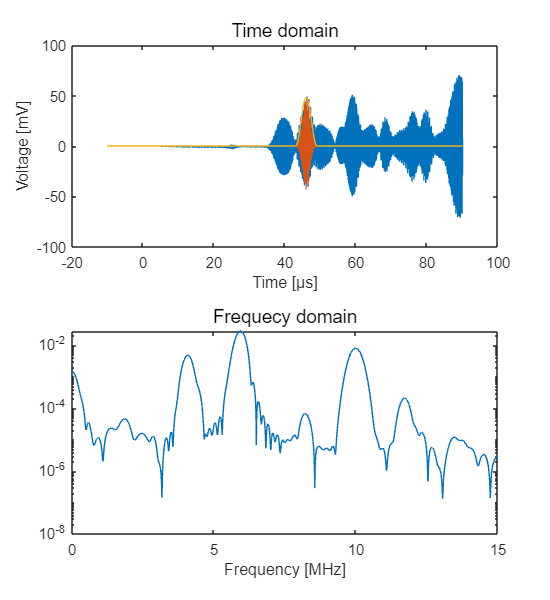

load('test_data\data20231127-113905-trimed.mat'); %テスト用波形読み込み(timevec, waveform1, waveform2, waveform1and2を含む)
y = waveform1and2; %フーリエ変換対象の波形
x = timevec;       %フーリエ変換対象の波形の時間軸
xStart = 43e-6; %窓関数をかける時間範囲（左端）
xEnd = 49e-6;   %窓関数をかける時間範囲（右端）
figure()
common.wfft(y,x,xStart,xEnd);
xlim([0 15]);

方形窓を指定すると，一つ一つのローブが鋭くなり周波数分解能を上げることができますが，多くのサイドローブが発生します．この例ではハン窓では8 MHz付近に確認できていたピークが，強い6 MHz成分のサイドローブに埋もれています．

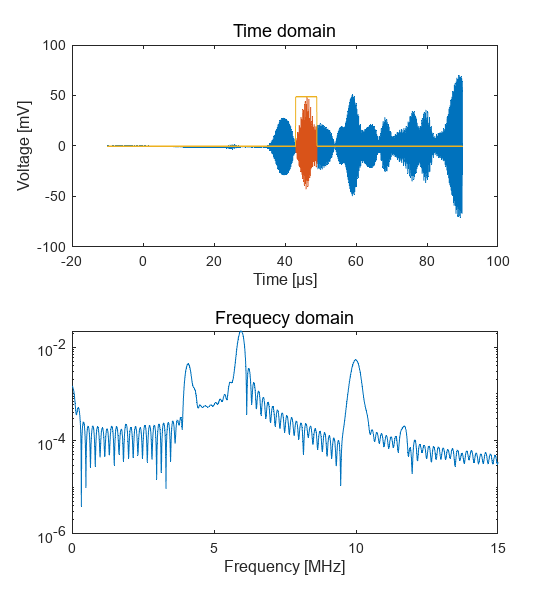

figure()
common.wfft(y, x, xStart, xEnd, Window="rect"); %方形窓
xlim([0 15]);

ガウス窓を使用すると，理想的にはサイドローブを完全に消す事ができます．ハン窓で発生していた6 MHzのサイドローブが消えていることに注目ください．一方で時間的には広い範囲の影響を受けるため，「何μ秒から何μ秒までの時間範囲の周波数分布」と言いづらいという欠点があります．

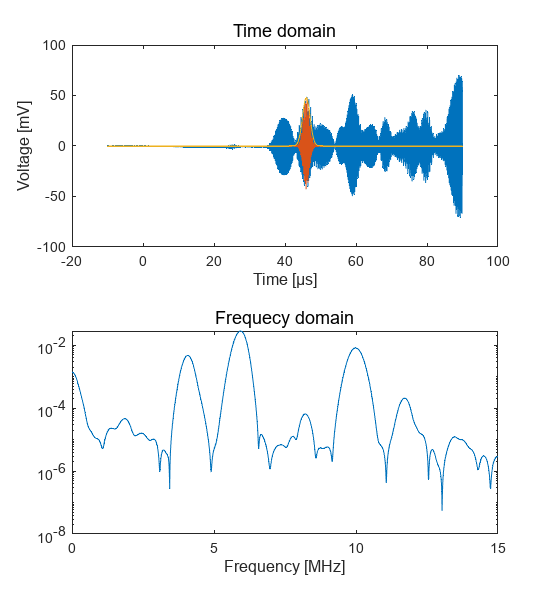

figure()
common.wfft(y, x, xStart, xEnd, Window=common.gauss(2.0)); %2σガウス窓（端がない純粋なガウス関数）
xlim([0 15]);

### ゼロ点補正を行う

ゼロ点補正を行わない場合，アンプのDCドリフトなどの影響により，大きなDC成分が乗る場合があります．

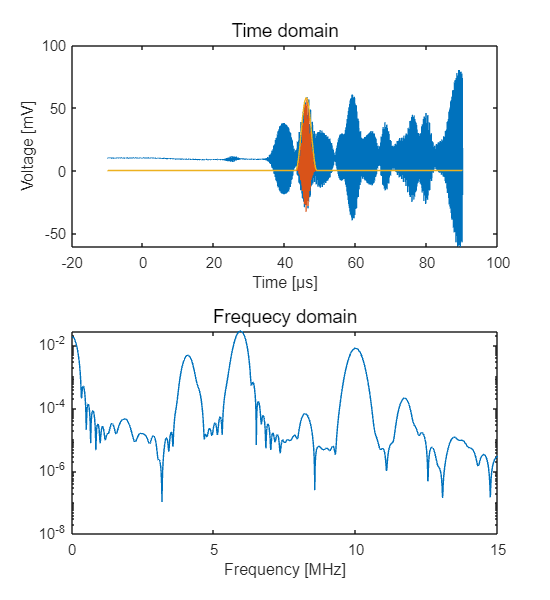

load('test_data\data20231127-113905-trimed.mat'); %テスト用波形読み込み(timevec, waveform1, waveform2, waveform1and2を含む)
y = waveform1and2 + 0.01; %フーリエ変換対象の波形(DCドリフトを再現）
x = timevec;       %フーリエ変換対象の波形の時間軸
xStart = 43e-6; %窓関数をかける時間範囲（左端）
xEnd = 49e-6;   %窓関数をかける時間範囲（右端）
common.wfft(y,x,xStart,xEnd);
xlim([0 15]);

このような場合に，ある区間の時間信号をフロアレベルとみなして，その区間の平均電圧が0になるように，波形全体をシフトさせることで，DC成分の影響を抑える事ができます．

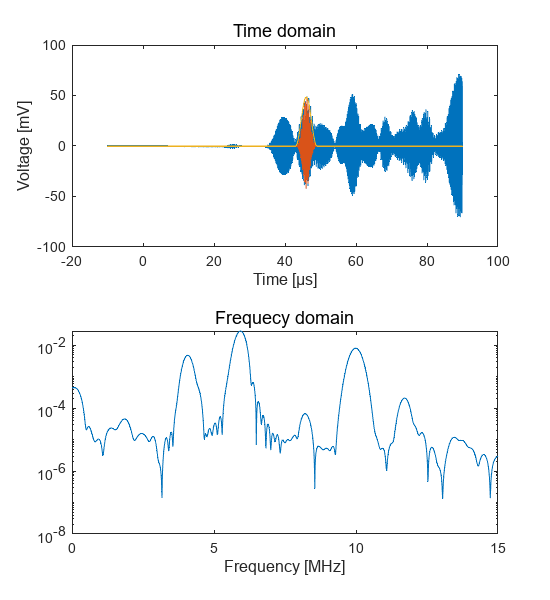

figure()
common.wfft(y,x,xStart,xEnd,ZeroAdjustment=true, ZeroRange=[-inf 20e-6]);
xlim([0 15]);

ゼロ点補正を行わない場合に比べて，周波数0の成分が減っていることがわかります．

### 0 padding点数を指定してフーリエ変換

フーリエ変換の点数が少ないとき，同じ信号を対象としていても周波数解析の刻みが少なくなることがあります．テストデータに対して窓をかけてフーリエ変換を行います．

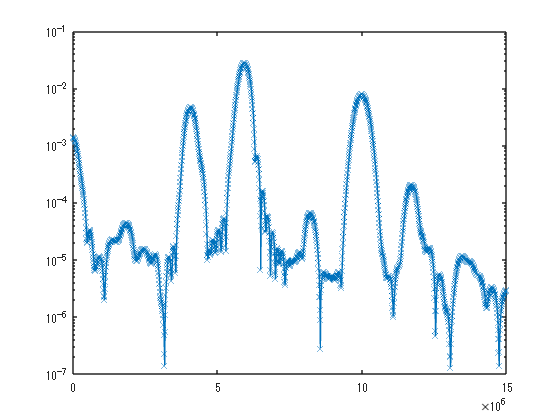

load('test_data\data20231127-113905-trimed.mat'); %テスト用波形読み込み(timevec, waveform1, waveform2, waveform1and2を含む)
x = timevec;       %フーリエ変換対象の波形の時間軸
y = waveform1and2; %フーリエ変換対象の波形
xStart = 43e-6; %窓関数をかける時間範囲（左端）
xEnd = 49e-6;   %窓関数をかける時間範囲（右端）
[Fy, Fx] = common.wfft(y,x,xStart,xEnd);
figure()
semilogy(Fx, Fy,'x-');
xlim([0 15e6]);

ここではフーリエ変換の点数が少ないことによる問題を強調するために，意図的に狭い時間範囲の波形データを用意します．

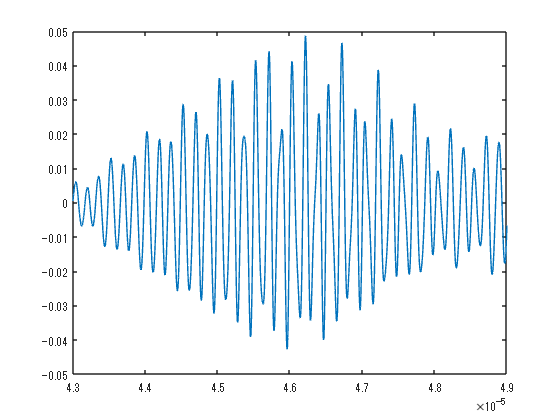

y_trimed = y(x>= xStart & x<= xEnd); %波形の一部を切り出す．
x_trimed = x(x>= xStart & x<= xEnd); 
plot(x_trimed,y_trimed);

このデータにフーリエ変換を行うと，先程のフーリエ変換の結果と同じですが，周波数の刻みが大きい，荒いデータが得られます．

例えば実験的に上記の範囲の波形しか取れていない場合を考えるとこのフーリエ変換の結果から，ピークの大きさや周波数などを評価するのは困難です．

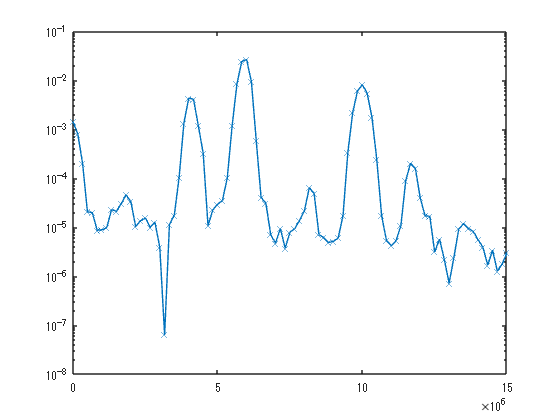

[Fy, Fx] = common.wfft(y_trimed,x_trimed,xStart,xEnd);
semilogy(Fx, Fy,'x-');
xlim([0 15e6]);

波形の末尾にゼロばかりが続くベクトルを加えて(0 padding）からフーリエ変換を行うと，フーリエ変換の結果に影響を与えずに解析する周波数刻みを増やすことができます．`このオプションはexpandPtsによって指定します`．

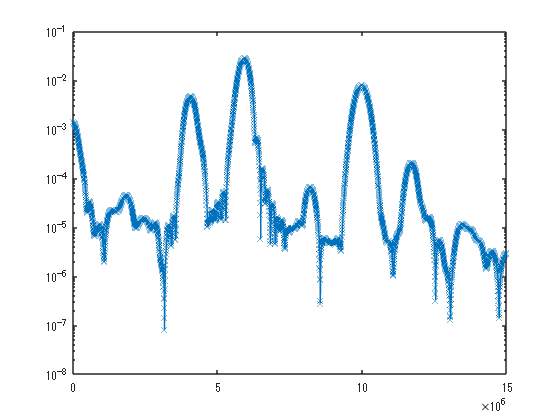

[Fy, Fx] = common.wfft(y, x, xStart, xEnd, 2e5);
semilogy(Fx, Fy,'x-');
xlim([0 15e6]);

参考：MATLAB既存のfftリファレンスの「[FFTの内挿](https://jp.mathworks.com/help/matlab/ref/fft.html#mw_b6c10d38-03f2-4c5e-80af-7a2930956b5b)」

## 入力引数

#### y     --- 入力信号

数値ベクトル．時間的な信号（波形）を与えることが多いです．

複素数ベクトルも受けることができますが，デフォルトではwfftは振幅のみを返すので，Complexオプションの指定も検討が必要です．

なお，MATLABの標準fft関数では行列を受けることもできますが，今のところwfftではサポートしていませんので注意が必要です．

#### x     --- 入力信号に対応した軸

実数ベクトル．入力信号yの軸．

#### xStart，xEnd --- 窓関数の幅

実数スカラー．既定値`xStart = x(1), xEnd = x(end).`

有限の幅で0になる窓（ハン窓，矩形窓など）の場合は，端の値を与えます．

また，ガウス窓などの幅が無限長さの窓の場合は正規化された幅で1となる点（例えば3σとなる点を±1に設定したガウス窓を用いる場合，±3σの点）を与えます．

#### expandPts  --- 最小FFT長

非負整数スカラー．既定値 0．

0 paddingを行い，FFTをを行う点数が少なくともexpandPtsの長さになるようにします．元々の信号がexpandPts以上であれば，特に何も行われません．

### 名前と値の引数

オプションの引数のペアを `Name1=Value1,...,NameN=ValueN` として指定します。ここで、`Name` は引数名で、`Value` は対応する値です。名前と値の引数は他の引数の後に指定しなければなりませんが、ペアの順序は重要ではありません。

#### Window --- 窓関数

"hann" (既定値) | "rect" | function_handle

関数ハンドルあるいは関数名(char/string)

窓関数を指定します．

文字列で'hann', 'rect'のように関数名を指定するか，規格化された窓関数の関数ハンドルを渡してください．

commonで提供されているな窓関数の関数ハンドルは

- common.hann　　ハン窓

- common.rect            矩形窓

- common.gauss(sigma)　ガウス窓

- common.gaussRect(sigma)　ガウス窓を矩形窓で切った窓

- common.tukey(ratio)　　テューキー窓

です．詳細は窓関数のリファレンスを参照ください．

#### ZeroAdjustment -- ゼロ点補正

"off"（既定値） | "on" | logical

  ゼロ点補正を行う場合"on"を指定します．デフォルトでは波形全体の平均を波形から引きますが，

  ZeroRangeオプションを設定することで，平均をとる時間範囲を設定できます．

#### ZeroRange --　ゼロ点補正を行うための平均範囲

[-inf inf]（既定値） | ベクトル

  ゼロ点補正を行うx軸の範囲を指定します．

#### AmpCompensate -- 振幅補正

"on"（既定値） | "off" | logical

  FFTの点数で割ることにより，ある成分のFFTの結果を，FFTをかけた範囲の

  平均的なその成分の振幅と一致させます．窓関数がrect（方形窓）以外の場合，

  窓関数の積分値で補正します．

#### Complex -- 複素数領域の結果を返す

"off"（既定値） | "on" | logical

  "on"の場合，フーリエ変換を複素数で返します．この場合，結果には

  位相情報も含んだ値になります．

#### Display -- FFTの結果の表示

"off"（既定値） | "on" | logical

  "on"を指定した場合，出力引数を設定せずにwfft( ___ )を使用した場合と同様に，結果を

  現在のFigureウィンドウに表示します．

## 出力引数

#### Fy --- フーリエ変換

数値ベクトル．Complexオプションが指定していない場合は実数の振幅を，Complexオプションが指定されている場合は，位相情報をもつ複素振幅を返します．

#### Fx --- 周波数軸

実数ベクトル．Fyの周波数軸を返します．

#### beforeFFT --- FFT前の波形

数値ベクトル．ゼロ点補正，Windowing，0 padding後のFFT直前の波形．

#### WindowFun --- 信号にかける窓関数

関数ハンドル．入力信号yの軸xを与えると，yにかける窓関数のベクトルが得られる．

## アルゴリズム

## 参照

[commonライブラリ](matlab:open('./common_reference.mlx'))